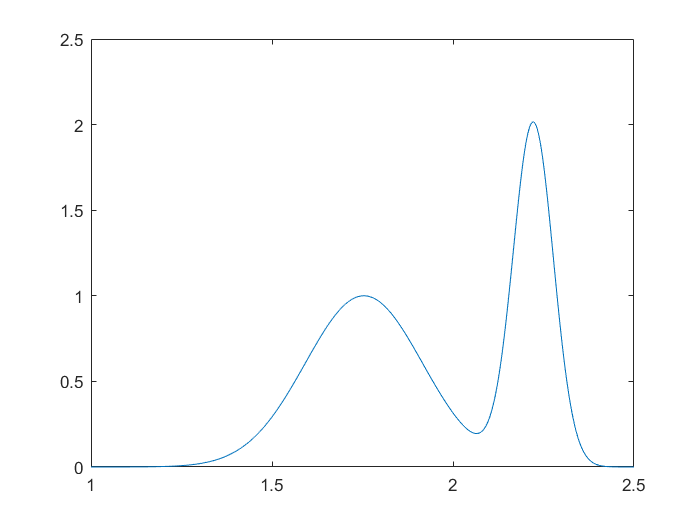

clc;clear all;
format short g
k_blue = 13.96;
k_yellow = 11.02;
sigma_blue = 0.4941;
sigma_yellow = 1.439;
BYration = 2;
wavenumber = linspace(1,2.5,1024);
guass = BYration*exp(-((2*pi*wavenumber-k_blue)/sigma_blue).^2)+exp(-((2*pi*wavenumber-k_yellow)/sigma_yellow).^2);
plot(wavenumber,guass);

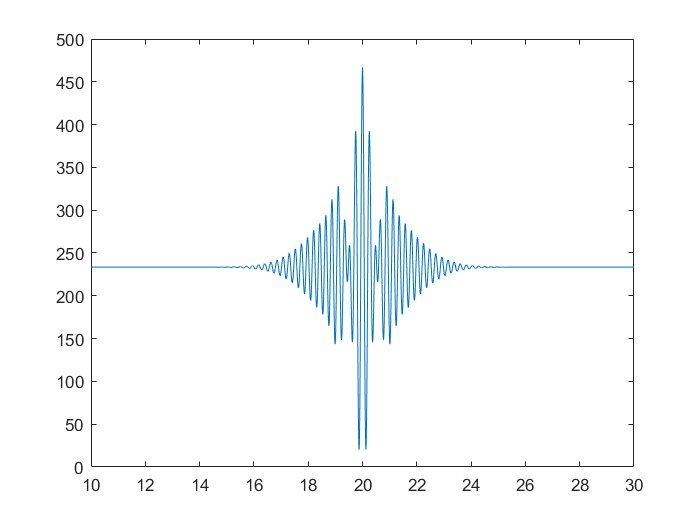

%生成非对称的多峰光谱
z0 = 20;    %单位为微米
N = 40000;
z = 10:30/40000:(N-1)*(30/40000);
spectrum_frequency = wavenumber;
spectrum_intensity = guass;
interference_signal = zeros(1,length(z));
for i = 1:length(z)
        interference_signal(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*(spectrum_frequency)));
end
% disp("生成的白光干涉信号");
plot(z,interference_signal);

*Next we investigate the effects of the phosphor-based LED on three reconstruction algorithms proposed by Mingzhou et al. [1], Ai and Novak [3], and de Groot and Deck [4], respectively. Among these three algorithms, only the de Groot and Deck approach is a phase-based approach; the other two are fringe-contrast-based approaches. Among these two methods, the major difference is that the Mingzhou et al. method assumes the fringe contrast function is a Gaussian signal, while the centroid approach does not assume this. *

*Simulation is used for investigating the effects of the phosphor-based LED on the reconstructed profile. Two sets of data are simulated: one is based on light with a Gaussian spectrum; another one is based on a phosphorbased LED, LXHL-LW6C by LumiLEDs. A line profile of 1 μm step height is selected; the line profile consists of 256 surface points, and each surface point has a corresponding intensity response. The sampling interval of the intensity response is 50 nm, and each intensity response is corrupted by Gaussian white noise (zero mean, variance of 0.01).*

%带有噪声的干涉信号，噪声均值为0，方差为0.005，光谱为高斯
Mytype=fittype('A*exp(-(x-u)^2/(2*d^2))');%需要拟合的函数类型
[cf ,gof]=fit(wavenumber',guass',Mytype)%fit函数

cf =      General model:
     cf(x) = A*exp(-(x-u)^2/(2*d^2))
     Coefficients (with 95% confidence bounds):
       A =      0.8578  (0.8105, 0.9052)
       d =      0.3585  (0.3316, 0.3855)
       u =       1.979  (1.955, 2.004)

gof = 包含以下字段的 struct :
           sse: 160.66
       rsquare: 0.38274
           dfe: 1021
    adjrsquare: 0.38153
          rmse: 0.39668


guassfun=cf.A*exp(-(wavenumber-cf.u).^2/(2*cf.d^2));
% plot(wavenumber,guassfun);
%带有噪声的干涉信号，噪声均值为0，方差为0.005,光谱为phosphorbased LED(多峰)
z0 = 20;    %单位为微米
N = 40000;
z = 10:30/40000:(N-1)*(30/40000);
spectrum_frequency = wavenumber;
spectrum_intensity = guass;
spectrum_intensity2 = guassfun;
interference_signal1 = zeros(1,length(z));
interference_signal2 = zeros(1,length(z));
zs = zeros(1,256);
zs2 = zeros(1,256);
zhongxin1= zeros(1,256);
zhongxin2= zeros(1,256);
baoluoguass = zeros(1,256);
baoluoguass2 = zeros(1,256);
for n = 1:256
noise = gnoise(0,0.010,length(z));
for i = 1:length(z)
        interference_signal1(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0+noise(i)).*(spectrum_frequency)));

        interference_signal2(i) = sum(spectrum_intensity2./2+...
        spectrum_intensity2./2.*cos(4*pi*(z(i)-z0+noise(i)).*(spectrum_frequency)));
end
% disp("生成的白光干涉信号");
% plot(z,interference_signal);
%傅里叶变换
%对白光干涉信号进行傅里叶变换,由于直流项的存在，补零操作会导致频域震荡。
%滤除直流项
interference_signal = interference_signal1;
interference_signal = interference_signal-mean(interference_signal);
Nftt = 2^18;
f_interference_signal = fft(interference_signal,Nftt);
Fs = 1/(30/40000);
deltaSigma = Fs/(2*Nftt);
sigma = (0:Nftt/2)*deltaSigma;
abs_fis = abs(f_interference_signal(1:Nftt/2+1))*2/Nftt;
ang_fis = angle(f_interference_signal(1:Nftt/2+1));
ang_fis = unwrap(ang_fis);
%对应频率1.1-2.1
[~, indix_min] = min(abs(sigma-1.5));
[~, indix_max] = min(abs(sigma-2.4));
% plot(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max),'LineWidth',2);
% plot(sigma(indix_min:indix_max),abs_fis(indix_min:indix_max),'LineWidth',2);
p = polyfit(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max),1);
zs(n) = p(1)/(-4*pi)+z(1);

%傅里叶变换
%对白光干涉信号进行傅里叶变换,由于直流项的存在，补零操作会导致频域震荡。
%滤除直流项
interference_signal = interference_signal2;
interference_signal = interference_signal-mean(interference_signal);
Nftt = 2^18;
f_interference_signal2 = fft(interference_signal,Nftt);
Fs = 1/(30/40000);
deltaSigma = Fs/(2*Nftt);
sigma = (0:Nftt/2)*deltaSigma;
abs_fis2 = abs(f_interference_signal2(1:Nftt/2+1))*2/Nftt;
ang_fis2 = angle(f_interference_signal2(1:Nftt/2+1));
ang_fis2 = unwrap(ang_fis2);
%对应频率1.1-2.1
[~, indix_min] = min(abs(sigma-1.5));
[~, indix_max] = min(abs(sigma-2.4));
% plot(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max),'LineWidth',2);
% plot(sigma(indix_min:indix_max),abs_fis(indix_min:indix_max),'LineWidth',2);
p2 = polyfit(sigma(indix_min:indix_max),ang_fis2(indix_min:indix_max),1);
zs2(n) = p2(1)/(-4*pi)+z(1);


%重心法：

interference_signal = interference_signal1;
zhongxin = zxf(interference_signal);
zhongxin = round(zhongxin);
zhongxin1(n) = z(zhongxin);

interference_signal = interference_signal2;
zhongxin = zxf(interference_signal);
zhongxin = round(zhongxin);
zhongxin2(n) = z(zhongxin);


采用相干峰寻址法测量：高斯包络拟合法（白光干涉光强曲线符合高斯包络调制，对白光 干涉光强的高斯包络进行拟合，取其极值点的横坐 标就是该点对应的相干峰的坐标）

interference_signal = interference_signal1;
interference_signal = interference_signal-mean(interference_signal);%双峰
baoluo = hilbert(interference_signal); 
baoluo = abs(baoluo);
% plot(z,interference_signal);
guass = fit(z.',baoluo.','gauss1');
baoluoguass(n) = guass.b1;

interference_signal = interference_signal2;
interference_signal2 = interference_signal-mean(interference_signal);%高斯
baoluo = hilbert(interference_signal2); 
baoluo = abs(baoluo);
% plot(z,interference_signal2);
guass = fit(z.',baoluo.','gauss1');
baoluoguass2(n) = guass.b1;
end
std(zs)

ans =      0.023705


% mean(zs)

std(zs2)

ans =     0.0042156


% mean(zs2)

std(zhongxin1)

ans =      0.029586


% mean(zhongxin1)

std(zhongxin2)

ans =      0.017167


% mean(zhongxin2)


std(baoluoguass)

ans =     0.0097232


% mean(baoluoguass)

std(baoluoguass2)

ans =     0.0048038


% mean(baoluoguass2)

function noise = gnoise(mean1,std1,N)
MU=mean1;
SIGMA=std1;
noise(1:N)=0;
corn=15;%%%180
han=hanning(corn);%Extension=60;
han=han';
NOISE1=normrnd(MU,SIGMA,1,N+corn);%NOISE2=normrnd(MU,SIGMA,1,N+Extension);
for no=1:N
ii=no;
noise(ii)=sum(han.*NOISE1(ii:ii+corn-1))/corn;%%%%100/24差不多4um不懂含义。。。。
end
noise1 = noise(1:N);
noise1_mean = mean(noise1);
noise1_std = std(noise1);
noise = (noise1-noise1_mean)./noise1_std*SIGMA;
% noise_mean = mean(noise);
% noise_std = std(noise);
end

function center1 = zxf(I3)
I_V=diff(I3);
I_V1=I_V.^2;
xx=1:length(I_V1);
center1=sum(I_V1.*xx)/sum(abs(I_V1));
end